# Transverse Shear Locking in Shear-Deformable Plates `-` Cantilever Plate Subject to Vertical Distributed Load

## Introduction

Transverse-shear locking manifests in shear-deformable elements by means of spurious transverse-shear forces that render the element's behavior artificially stiffer than it should be. This effect has the following implications in the case that transverse-shear locking is apparent:

- The shear-force distribution is oscillatory

- The deformations are artifially stiffer than they should be

- The convergence rate is considerably reduced or even halted overall

- The effect of transverse-shear locking is proportional to the slenderness of the plate: the more slender the plate is, the more pronounced the effect of locking becomes

Selective reduced integration is not applicable in the case of two-dimensional elements. The reason is, that in two-dimensional plate elements 4 Gauss points are needed to correctly integrate the shear-part of the stiffness in the frame of the underlying `2x2` quadrature. Using one point per direction, the latter `2x2` quadrature reduces to a single Gauss point, namely, 3 Gauss points are removed. As a result, spurious energy modes become apparent and thus the global stiffness matrix becomes singular. These additional spurious energy modes need then be supressed, so that selective reduced integration can be effectively applied for two-dimensional shear-deformable plate elements. Other methods for the alleviation of transverse shear locking for two-dimensional plate elements include:

- Use of high-order basis functions

- Use of advanced techniques such as Assumed Natural Strains (ANS) or other (EAS, etc.)

The problem addressed herein is that of a rectangular plate subject to distributed vertical load, acting as a cantilever plate, see the following figure:

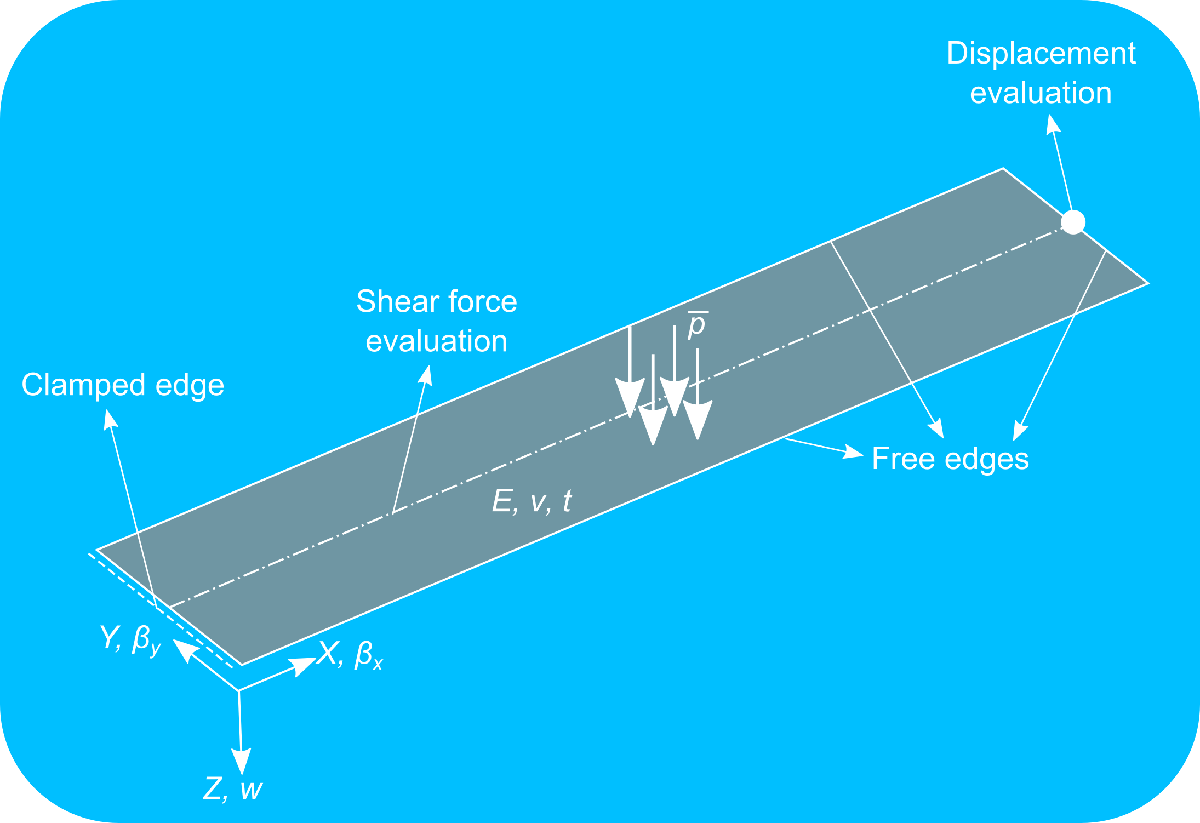

The analytical solution of the latter setup is discussed in Live Script [`main_Chapter2_AShearDeformablePlateElement.mlx`](matlab:open('..\2_ReissnerMindlinPlate\main_Chapter2_AShearDeformablePlateElement.mlx')), namely,


$$w(X,Y) = \frac{1}{\alpha G A} \left( \overline{p} L X - \frac{\overline{p} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{p} X^4}{24} + \frac{\overline{p} L X^3}{6} - \frac{\overline{p} L^2 X^2}{4} \right) \qquad (1.1) \\
\beta(X,Y) = \int_0^L - \frac{1}{\alpha G A} \overline{p} - \frac{\text{d}^2 w}{\text{d} x^2} \; \text{d} X \qquad \qquad \qquad \qquad \;\;\,\qquad  \qquad  \quad \;\; (1.2)$$


The analytical solution in Eqs. (1.1) and (1.2) can be obtained in a single line of code using the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®, see this code section.

This solution will be then used to determine the resultant transverse shear force $q_x$, which is given in this case by the following relationship:


$$q_x(X,Y) = \alpha G A \gamma_x(X,Y) = \alpha G A \left( \frac{\partial w}{\partial X} + \beta_y \right) \qquad (2)$$


We will then use this reaction transverse shear force to demonstrate how transverse shear locking can be detected.

[PREVIOUS Chapter](matlab:open('..\4_TransverseShearLocking_TimoshenkoBeam\main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')) *Transverse-Shear Locking in Timoshenko beam elements - Cantilever Beam Subject to Vertical Distributed Load*

[NEXT Chapter](matlab:open('..\4_TransverseShearLocking_ReissnerMindlinSquarePlate\main_Chapter4_Locking_ReissnerMindlinSquarePlate.mlx')) *Transverse-Shear Locking in Shear-Deformable Plates *`-`* Two Sided Clampled Plate Subject to Vertical Distributed Load*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem parameters**

### Geometric parameters

Thickness of the plate [m]

propStr.t = 10^(-1);

X-coordinate of left corner [m]

X0 = 0;

X-coordinate of right corner [m]

XLx = 4;

Y-coordinate of left corner [m]

Y0 = 0;

Y-coordinate of right corner [m]

YLy = 1;

### Material paramerters

Distributed load [N/m^2]

propStr.pBar = -1e2;

Distributed moment around x-axis [N/m]

propStr.mxBar = 0;

Distributed moment around y-axis [N/m]

propStr.myBar = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/2/(1 + propStr.nu);

Plate's stiffness [Nm]

propStr.D = propStr.E*propStr.t^3/12/(1 - propStr.nu^2);

Shear-correction factor

propStr.alpha = 5/6;

### Newton-Raphson properties for the inversion of the geometry map

Convergence tolerance

propNewtonRaphson.eps = 1e-9;

Maximum number of iterations

propNewtonRaphson.maxIt = 10;

## Analytical solution using the Timoshenko beam formulation

Since the plate is rectangular, clamped on its one end while being subject to constant distributed vertical load its behavior is expected to resemble a beam aligned with the X-axis, whereas no effects are expected to take place along the Y-axis. The analytical solution for this problem using the shear-deformable Timoshenko beam formulation are in this case as follows

### Auxiliary variables

syms wEx(X) betayEx(X) qxEx(X) Lsym psym Gsym Aqsym ...
    Esym Isym tsym alphaScf

### Analytical solution with respect to the vertical deflection

Set the analytical solution in terms of the vertical deflection field (Eq. (1) in the introduction):


$$w(X,Y) = \frac{1}{\alpha G A} \left( \overline{p} L X - \frac{\overline{p} X^2}{2} \right) - \frac{1}{EI} \left( - \frac{\overline{p} X^4}{24} + \frac{\overline{p} L X^3}{6} - \frac{\overline{p} L^2 X^2}{4} \right) \qquad (3)$$


namely:

wEx(X) = (psym*Lsym*X-psym*X^2/2)/Gsym/(Aqsym) - ...
    (-psym*X^4/24+psym*Lsym*X^3/6-psym*Lsym^2*X^2/4)/Esym/Isym;

### Analytical solution with respect to the transverse-shear forces

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) in [MATLAB](https://www.mathworks.com/products/matlab.html)


$$\beta(X,y) = \int_{0}^L - \frac{1}{\alpha G A}\overline{p} - \frac{\partial^2 w}{\partial x^2} \: \text{d}x  \qquad (4)$$


betayEx(X) = int(-1/(propStr.alpha*propStr.G*YLy*propStr.t)*...
    propStr.pBar - diff(diff(wEx, X), X));

### Analytical solution with respect to the transverse-shear forces

Herein we are concerned with the resultant transverse-shear force component $q_x(X,Y) = \alpha G t \gamma_x = \alpha G t \overbrace{\left( \frac{\partial w}{\partial X} + \beta_y \right)}^{\gamma_x}$ because $q_y(X,Y)$ is identically zero across the plate due to the given setup. Resultant transverse-shear force component $q_x(X,Y) $ is given by:

qxEx(X) = alphaScf*Gsym*tsym*(diff(wEx(X), X, 1) + betayEx(X));

### Substitution of the known parameters in the analytical expression

wExSubs(X) = subs(wEx,{Lsym, psym, Gsym, Esym, Isym, Aqsym}, ...
    {XLx, propStr.pBar, propStr.G, propStr.E, ...
    YLy*(propStr.t^3)/12, propStr.alpha*YLy*propStr.t});
betayExSubs(X) = subs(betayEx, {Lsym, psym, Gsym, Esym, Isym, Aqsym}, ...
    {XLx, propStr.pBar, propStr.G, propStr.E, YLy*(propStr.t^3)/12, ...
    propStr.alpha*YLy*propStr.t});

## Analytical expressions for the two-dimensional basis functions

### Analytical expressions for the bilinear basis functions


$$N_1^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad (5.1) \\
N_2^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad (5.2) \\
N_3^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 + \eta) \quad (\xi,\eta) \in [0, 1], \quad (5.3) \\
N_4^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 + \eta) \quad (\xi,\eta) \in [0, 1]. \quad (5.4)$$


syms N1Q1(xi, eta) N2Q1(xi, eta) N3Q1(xi, eta) N4Q1(xi, eta)
N1Q1(xi, eta) = (1 - xi)*(1 - eta)/4;
N2Q1(xi, eta) = (1 + xi)*(1 - eta)/4;
N3Q1(xi, eta) = (1 + xi)*(1 + eta)/4;
N4Q1(xi, eta) = (1 - xi)*(1 + eta)/4;
NQ1 = [N1Q1 N4Q1 N3Q1 N2Q1];

### Analytical expressions for the biquadratic basis functions


$$N_1^{Q_2}(\xi, \eta) = \frac{1}{4} \xi (\xi - 1) \eta (1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \quad \quad (6.1)  \\
N_2^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)(\xi - 1)\eta(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (6.2) \\
N_3^{Q_2}(\xi, \eta) = \frac{1}{4}(\xi + 1)\xi \eta(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \quad \quad (6.3) \\
N_4^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)\xi(\eta + 1)(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (6.4) \\
N_5^{Q_2}(\xi, \eta) = \frac{1}{4}(\xi + 1)\xi(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \quad \quad (6.5) \\
N_6^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)(\xi - 1)(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (6.6) \\
N_7^{Q_2}(\xi, \eta) = \frac{1}{4}\xi (\xi - 1)(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1],  \quad \quad \quad \quad \quad (6.7) \\
N_8^{Q_2}(\xi, \eta) = -\frac{1}{2}\xi (\xi - 1)(\eta + 1)(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (6.8) \\
N_9^{Q_2}(\xi, \eta) = \frac{1}{1}(1 - \xi^2) (1 - eta^2) \quad (\xi,\eta) \in [0, 1], 
 \quad\ \quad \quad \quad (6.9)\\$$


syms N1Q2(xi, eta) N2Q2(xi, eta) N3Q2(xi, eta) N4Q2(xi, eta) ...
    N5Q2(xi, eta) N6Q2(xi, eta) N7Q2(xi, eta) N8Q2(xi, eta) ...
    N9Q2(xi, eta)
N1Q2(xi, eta) = xi*(xi - 1)*eta*(eta - 1)/4;
N2Q2(xi, eta) = (xi + 1)*(xi - 1)*eta*(eta - 1)/-2;
N3Q2(xi, eta) = (xi + 1)*xi*eta*(eta - 1)/4;
N4Q2(xi, eta) = (xi + 1)*xi*(eta + 1)*(eta - 1)/-2;
N5Q2(xi, eta) = (xi + 1)*xi*(eta + 1)*eta/4;
N6Q2(xi, eta) = (xi + 1)*(xi - 1)*(eta + 1)*eta/-2;
N7Q2(xi, eta) = xi*(xi - 1)*(eta + 1)*eta/4;
N8Q2(xi, eta) = xi*(xi - 1)*(eta + 1)*(eta - 1)/-2;
N9Q2(xi, eta) = (xi + 1)*(xi - 1)*(eta + 1)*(eta - 1)/1;
NQ2 = [N1Q2 N7Q2 N5Q2 N3Q2 N8Q2 N4Q2 N2Q2 N6Q2 N9Q2];

 **Reflect**

How can the setup of these interpolatory basis functions be generalized?

## **Discretization**

Both the vertical deflection $w$ and cross-sectional rotation $\beta_x$, $\beta_y$ fields are discretized using the same basis (shape) functions, namely:


$$\begin{array}{l}
w\left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 1\right)\\
\beta_x \left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;\beta_{x,i} \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 2\right)\\
\beta_y \left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;\beta_{y,i} \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\ldotp 3\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### **Quadrilateral mesh**

#### Choose number of elements in the mesh

Number of elements along the X-direction

numElx = 12;

Number of elements along the Y-direction

numEly = 3;

Total number of elements

numEl = numElx*numEly;

#### Generation of a quadrilateral mesh

[nodesX, nodesY] = ...
    generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElx, numEly);

#### Rendering the mesh non-uniform

Check the following checkbox to render the mesh non-uniform **Note **This only works for numElx = 4 and numEly = 2 with the given values

isMeshNonUniform = false;
if isMeshNonUniform
    if numElx ~= 4 || numEly ~= 2
        error("Making the mesh non-uniform only works for numElx = 4 and numEly = 2")
    end

Displace node 2

    nodesY(2, 1) = nodesY(2, 1) + 0.08; % y

Displace node 5

    nodesX(2, 2) = nodesX(2, 2) + 0.08; % x
    nodesY(5, 1) = nodesY(5, 1) - 0.08; % y    

Displace node 8

    nodesX(2, 3) = nodesX(2, 3) - 0.08; % x
    nodesY(8, 1) = nodesY(8, 1) + 0.08; % y

Displace node 11

    nodesX(2, 4) = nodesX(2, 4) + 0.08; % x
    nodesY(11, 1) = nodesY(11, 1) + 0.08; % x

displace node 14

    nodesY(14, 1) = nodesY(14, 1) - 0.08; % x

end

  **Try**

Use a non-uniform mesh by unselecting the checkbox in this code section.

 **Reflect**

Do you still expect a numerical solution from FEM that matches the analytical one?

### **Four-noded bilinear quadrilateral mesh**

#### Mesh generation

numNodesElQ1 = 4;
mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodesQ1 = height(mshQ1.nodes);

#### Dirichlet boundary conditions for the mesh with the bilinear quadrilateral elements

[freeDOFsQ1, homDOFsQ1] = ...
    utilityFunctionsCantileverPlate.getFreeDOFsBilinearQuadrilateralMesh ...
    (numNodesQ1, numEly);

#### Mesh plot

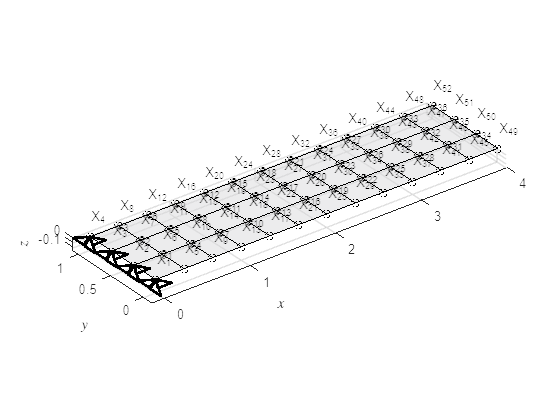

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ1, numVertices, true);

hold on;
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshQ1.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", Interpreter="latex")
ylabel("$y$", Interpreter="latex")
zlabel("$z$", Interpreter="latex")

#### Display the mesh with the basis functions

isPlotBasisFunctions = false;
if isPlotBasisFunctions
    syms xi eta
    NQ1Vis = {(1 - xi)*(1 - eta)/4, (1 - xi)*(1 + eta)/4, ...
        (1 + xi)*(1 + eta)/4, (1 + xi)*(1 - eta)/4};
    [h5, h6, h7] = plotMeshAndBasisFunctions2d(mshQ1, NQ1Vis, true);
end

  **Try**

Select the checkbox in this code section to create an animation for the bilinear basis functions throughout the mesh. Be aware that this code section can take very long to run due to rendering of complex graphics.

 **Reflect**

What is the support of the bilinear basis functions, namely, the area over which they are not identical zero?

### **Nine-noded biquadratic quadrilateral mesh**

#### Mesh generation

numNodesElQ2 = 9;
[mshQ2, ~] = generateBiquadraticQuadrilateralMesh ...
    (numElx, numEly, nodesX, nodesY, mshQ1, numNodesElQ1, numNodesElQ2);
numNodesQ2 = height(mshQ2.nodes);

#### Dirichlet boundary conditions for the mesh with the biquadratic quadrilateral elements

[freeDOFsQ2, homDOFsQ2] = ...
    utilityFunctionsCantileverPlate.getFreeDOFsBiquadraticQuadrilateralMesh ...
    (numNodesQ1, numNodesQ2, numEly);

#### Mesh plot

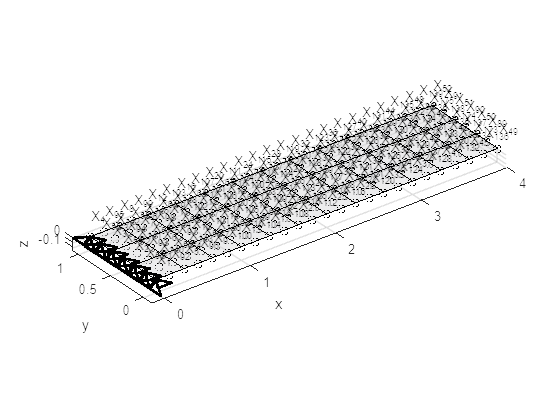

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ2, numVertices, true);
hold on;
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshQ2.nodes, homDOFsQ2, scalVer);

for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("z")

## Master stiffness matrix and load vector

### Four-noded bilinear Reissner-Mindlin elements

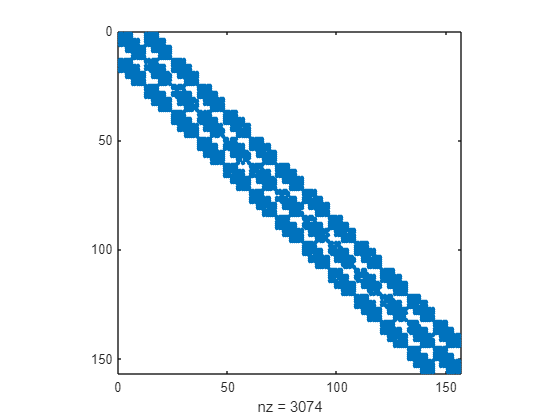

computeStiffMatrixandForceVectorQ1 = ...

    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ1 = ...
    @computeBilinearBasisFunctionsAndFirstDerivatives;
[KQ1, FQ1] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ1, computeBasisFunctionsAndDerivsQ1, ...
    computeStiffMatrixandForceVectorQ1, propStr);

Sparsity of the stiffness matrix

spy(KQ1)

  **Try**

Computation the master stiffness matrix corresponding to the reduced integration

 **Reflect**

Compute the rank of the stiffness matrix when using the selective reduced-integration. 

### Nine-noded biquadratic Reissner-Mindlin elements

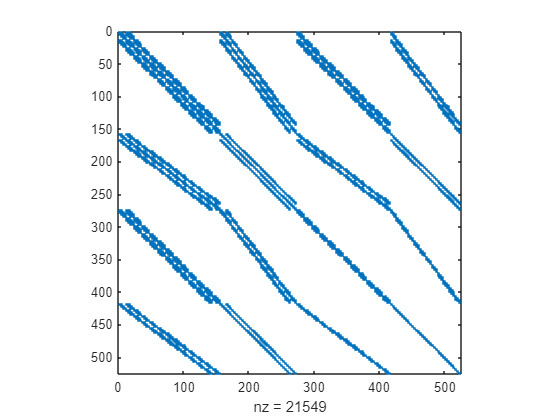

computeStiffMatrixandForceVectorQ2 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ2 = ...
    @computeBiquadraticBasisFunctionsAndFirstDerivatives;
[KQ2, FQ2] = computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ2, computeBasisFunctionsAndDerivsQ2, ...
    computeStiffMatrixandForceVectorQ2, propStr);

Sparsity of the master global stiffness matrix

spy(KQ2)

####  **Reflect**

Why is the sparsity pattern of the master stiffness matrix not aligned around the main-diagonal for the case of the biquadratic quadrilateral elements as compared to the bilinear quadrilateral elements?

## Solution of the Reissner-Mindlin plate problem

### Four-noded bilinear elements

#### Solution of the linear equation system

numDOFsQ1 = 2*numNodesQ1;
uQ1 = zeros(numDOFsQ1, 1);
uQ1(freeDOFsQ1, 1) = KQ1(freeDOFsQ1, freeDOFsQ1)\FQ1(freeDOFsQ1);

  **Try**

Solve the linear equation system using the selective reduced integration. Is the linear equation system solvable?

 **Reflect**

Name possible methods to circumvent this issue from the literature

#### Visualization of the solution in terms of the vertical displacement field

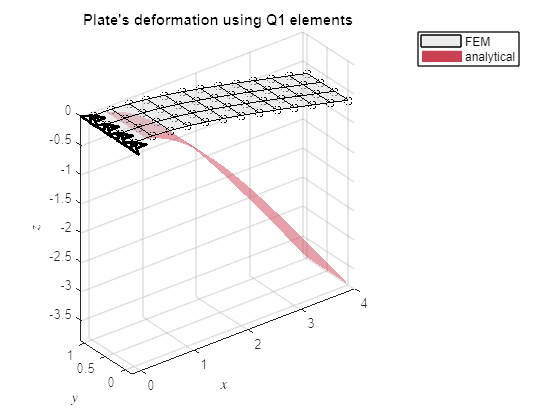

mshCurrQ1 = mshQ1;
scaling = 1;
mshCurrQ1.nodes(:, 3) = mshCurrQ1.nodes(:, 3) + ...
    scaling*uQ1(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1, numVertices, false);
hold on;
fsurf(wExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
legend("FEM", "", "analytical")
title("Plate's deformation using Q1 elements")

### Visualization of the solution in terms of the rotational field

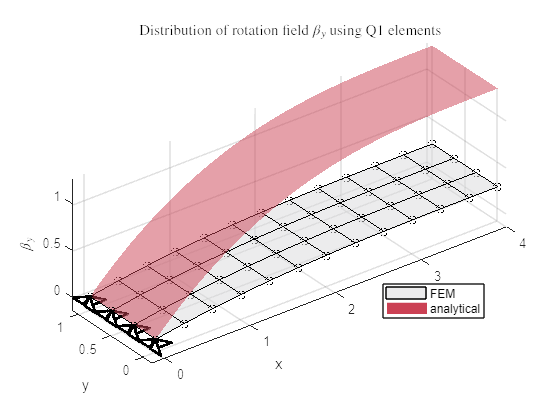

mshCurrQ1Betay = mshQ1;
scaling = 1;
mshCurrQ1Betay.nodes(:, 3) = mshCurrQ1Betay.nodes(:, 3) + ...
    scaling*uQ1(3:3:end);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1Betay, numVertices, false);
hold on;
fsurf(betayExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1Betay.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("$\beta_y$", Interpreter="latex")
legend("FEM", "", "analytical", Location="best")
title("Distribution of rotation field $\beta_y$ using Q1 elements", ...
    Interpreter="latex")

  **Try**

Plot the current configuration of the plate using bilinear quadrilateral elements and reduced-integration

 **Reflect**

What does the deformation pattern indicates for the elements whose stiffness matrix is computed using selective reduced-integration?

### Nine-noded biquadratic Reissner-Mindlin elements

#### Solution of the linear equation system

numDOFsQ2 = 2*numNodesQ2;
uQ2 = zeros(numDOFsQ2, 1);
uQ2(freeDOFsQ2, 1) = KQ2(freeDOFsQ2, freeDOFsQ2)\FQ2(freeDOFsQ2);

#### Visualization of the solution in terms of the vertical displacement field

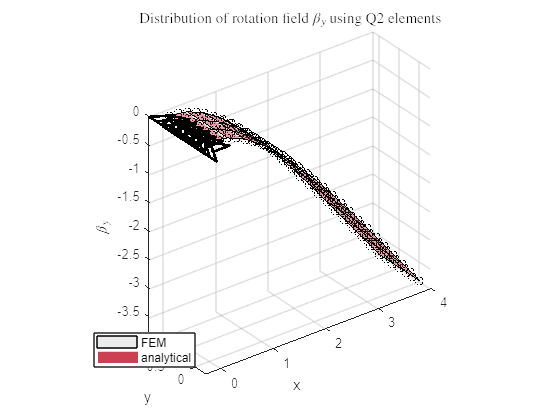

mshCurrQ2 = mshQ2;
scaling = 1;
mshCurrQ2.nodes(:, 3) = mshCurrQ2.nodes(:, 3) + ...
    scaling*uQ2(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ2, numVertices, false);
hold on;
fsurf(wExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("$\beta_y$", Interpreter="latex")
legend("FEM", "", "analytical", Location="best")
title("Distribution of rotation field $\beta_y$ using Q2 elements", ...
    Interpreter="latex")

### Visualization of the solution in terms of the rotational field

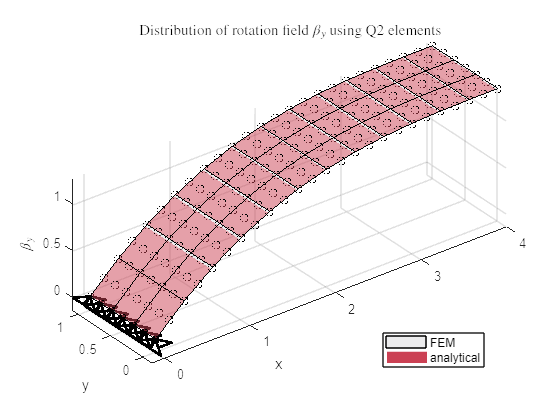

mshCurrQ2Betay = mshQ2;
scaling = 1;
mshCurrQ2Betay.nodes(:, 3) = mshCurrQ2Betay.nodes(:, 3) + ...
    scaling*uQ2(3:3:end);
numVertices = numel(mshQ2.nodes(:, 1));
plotMesh2d(mshCurrQ2Betay, numVertices, false);
hold on;
fsurf(betayExSubs, [X0 XLx Y0 YLy], FaceColor=[203 65 84]/255, ...
    FaceAlpha=0.5, LineStyle="none");
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2Betay.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("$\beta_y$", Interpreter="latex")
legend("FEM", "", "analytical", Location="best")
title("Distribution of rotation field $\beta_y$ using Q2 elements", ...
    Interpreter="latex")

## Transverse-shear locking due incompatible discretization spaces

The transverse-shear locking can be attributed to the incompatibility of the discretization space for the vertical displacement and rotation fields. This manifests as residual transverse-shear forces for thin plates which trigger this numerical artifact. More information on this topic you can find [here](matlab:open('./main_Chapter31_ReissnerMindlinCantileverPlate_ShearForces.mlx')) based on the Timoshenko beam problem.

In this section the shear forces $q_x = \alpha G t \gamma_x = \alpha G t \overbrace{\left( \frac{\partial w}{\partial X} + \beta_y \right)}^{\gamma_x}$are computed using both the bilinear and the biquadratic elements along the line $X = 0.5$ m.

### Number of evaluation points

numPts = 102;

  **Try**

Modify the number of evaluation points by means of variable `numPts`

 **Reflect**

- How do the different distributions of the transverse-shear force change with respect to the number of evaluation points and why?

- How many evaluation points do you need to appropriately describe the different transverse-shear force distributions? Is this value constant or does it depend on the chosen value for the beam's length and thickness, $L$ and $t$, respectively?

### Transverse-shear force distribution along the the plate's section

Navigate to [THIS](matlab:open('./main_Chapter41_ReissnerMindlinCantileverPlate_ShearForces.mlx')) Section for the detailed analysis.

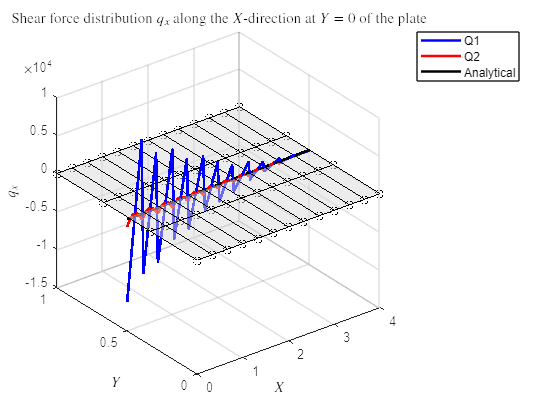

main_Chapter41_ReissnerMindlinCantileverPlate_ShearForces

## Slenderness study on transverse shear-locking

In this section it is investigated the behavior of the convergence as the slenderness (length over thickness) goes to infinity $L/t \rightarrow \infty$, namely, as the thickness goes to zero $t \rightarrow 0$. As the thickness goes to zero, the spurious forces due to transverse shear locking increase, leading to an ever increasing artificially stiffening behavior. To keep the solution constant the same scaling factor is applied both to the applied force and the thickness, so that the ratio $p/t$, and thus the resulting deformation, remains constant.

### Bounding exponents of ten

The space of the slenderness ratio is defined by means of power of ten, namely, $\lambda \in \left[ \begin{array}{cc} 10^{\text{\texttt{mPowL}}}, 10^{\text{\texttt{mPowU}}} \end{array} \right]$

mPowL = -3;
mPowU = 3;
if floor(mPowL) ~= mPowL || floor(mPowU) ~= mPowU
    error("Variables 'mPowL' and 'mPowU' must be integers")
end
if mPowL >= mPowU
    error("Integer 'mPowL' must be strictly smaller than integer 'mPowU'")
end

  **Try**

Modify the bounding values of the slenderness $\lambda $ by means of variables `mPowL` and `mPowU`

 **Reflect**

How does the slenderness space affect the slenderness graph below and why?

### Slenderness study

Navigate to [THIS](matlab:open('./main_Chapter42_ReissnerMindlinCantileverPlate_SlendernessStudy.mlx')) Section for the detailed analysis.

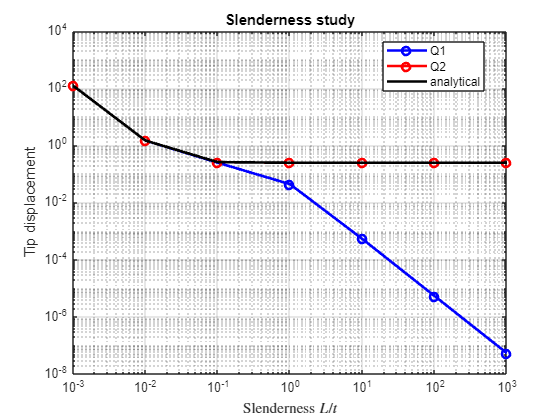

main_Chapter42_ReissnerMindlinCantileverPlate_SlendernessStudy

## Convergence study on transverse shear-locking

Another way to identify transverse shear locking is to perform a convergence study for different slenderness levels of the structure. A reduced convergence rate as the slenderness level increases indicates the presence of transverse shear-locking. In extreme transverse shear-locking cases the convergence rate drops to nearly zero

### Number of refinement levels

numRef = 50;
if floor(numRef) ~= numRef
    error("Variables 'numRef' must be an integer")
end
if numRef <= 0
    error("Variable 'numRef' must be strictly positive")
end

  **Try**

Modify the number of refinment levels using variable `numRef` for different slenderness values $\lambda$

 **Reflect**

How is the convergence rate affected by the different slenderness values $\lambda$?

### Choose point onto which to compute the displacement

xyPostProc = [XLx (0 + YLy)/2];

### Convergence study based on the tip plate's displacement

Navigate to [THIS](matlab:open('./main_Chapter43_ReissnerMindlinCantileverPlate_ConvergenceStudy.mlx')) section for the detailed analysis.

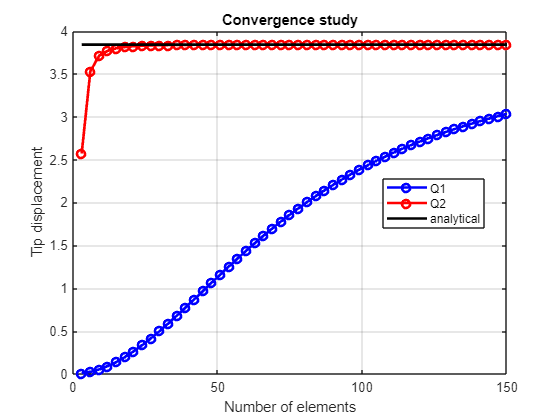

main_Chapter43_ReissnerMindlinCantileverPlate_ConvergenceStudy

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

[](https://doi.org/10.1007/978-3-540-78319-0)[[2] Brezzi, F., Boffi, D., Demkowicz, L., Durán, R. G., Falk, R. S., & Fortin, M. (2008). Mixed finite elements, compatibility conditions, and applications. *Springer*, *2*, 4-2.](https://doi.org/10.1007/978-3-540-78319-0)